# Regression Assignment Live Script

#### Initialization

clear; clc; close all

## Load, Split Data and apply Pre-Processing

data = load('airfoil_self_noise.dat');
[trnData, chkData, tstData] = split_scale(data, 'MinMaxDiff');

## Define Models

#### TSK 1

tsk1_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk1_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk1_genfisOptions);
tsk1_anfisOptions = anfisOptions('InitialFIS', tsk1_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-2

tsk2_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'constant');
tsk2_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk2_genfisOptions);
tsk2_anfisOptions = anfisOptions('InitialFIS', tsk2_initFIS, ...
                'EpochNumber', 200, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);
            

#### TSK-3

tsk3_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 2, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk3_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk3_genfisOptions);
tsk3_anfisOptions = anfisOptions('InitialFIS', tsk3_initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### TSK-4

tsk4_genfisOptions = genfisOptions('GridPartition', ...
                'NumMembershipFunctions', 3, ...
                'InputMembershipFunctionType', 'gbellmf', ...,
                'OutputMembershipFunctionType', 'linear');
tsk4_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk4_genfisOptions);
tsk4_anfisOptions = anfisOptions('InitialFIS', tsk4_initFIS, ...
                'EpochNumber', 100, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

### Train Models

#### Train TSK 1

[tsk1_trnFIS, tsk1_trnError, ~, tsk1_valFIS, tsk1_valError]=anfis(trnData, tsk1_anfisOptions);

ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 32
	Number of nonlinear parameters: 30
	Total number of parameters: 62
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 4.43883 	 4.22322
2 	 4.41128 	 4.18605
3 	 4.38401 	 4.14932
4 	 4.35708 	 4.11309
Step size increases to 0.011000 after epoch 5.
5 	 4.33053 	 4.07742
6 	 4.30442 	 4.04237
7 	 4.27623 	 4.0046
8 	 4.24867 	 3.96773
Step size increases to 0.012100 after epoch 9.
9 	 4.22177 	 3.93182
10 	 4.19558 	 3.89695
11 	 4.16763 	 3.85987
12 	 4.14061 	 3.82419
Step size increases to 0.013310 after epoch 13.
13 	 4.11456 	 3.78997
14 	 4.0895 	 3.75727
15 	 4.06312 	 3.7231
16 	 4.038 	 3.69086
Step size increases to 0.014641 after epoch 17.
17 	 4.01414 	 3.66057
18 	 3.99156 	 3.63225
19 	 3.9682 	 3.60338
20 	 3.94638 	 3.57687
Step size increases to 0.016105 after epoch 21.
21 	 3.92608 	 3.55271
22 	 3.90729 	 3.53084
23 	 3.888

#### Train TSK 2

[tsk2_trnFIS, tsk2_trnError, ~, tsk2_valFIS, tsk2_valError]=anfis(trnData, tsk2_anfisOptions);

ANFIS info:
	Number of nodes: 524
	Number of linear parameters: 243
	Number of nonlinear parameters: 45
	Total number of parameters: 288
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 243


Start training ANFIS ...

1 	 3.55545 	 5.80412
2 	 3.53694 	 5.59506
3 	 3.52015 	 5.37638
4 	 3.49833 	 5.12463
Step size increases to 0.011000 after epoch 5.
5 	 3.46372 	 4.83637
6 	 3.41769 	 4.54827
7 	 3.36178 	 4.28275
8 	 3.30699 	 4.09776
Step size increases to 0.012100 after epoch 9.
9 	 3.25697 	 3.98784
10 	 3.21299 	 3.93122
11 	 3.17153 	 3.90433
12 	 3.13646 	 3.89529
Step size increases to 0.013310 after epoch 13.
13 	 3.10673 	 3.89309
14 	 3.08129 	 3.89246
15 	 3.05719 	 3.89059
16 	 3.03617 	 3.88603
Step size increases to 0.014641 after epoch 17.
17 	 3.01735 	 3.87815
18 	 3.00001 	 3.86742
19 	 2.982 	 3.85429
20 	 2.96457 	 3.84306
Step size increases to 0.016105 after epoch 21.
21 	 2.94732 	 3.83737
22 	 2.92996 	 3.84018
23

#### Train TSK 3

[tsk3_trnFIS, tsk3_trnError, ~, tsk3_valFIS, tsk3_valError]=anfis(trnData, tsk3_anfisOptions);

ANFIS info:
	Number of nodes: 92
	Number of linear parameters: 192
	Number of nonlinear parameters: 30
	Total number of parameters: 222
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 32


Start training ANFIS ...

1 	 2.98157 	 3.38329
2 	 2.9665 	 3.35873
3 	 2.95149 	 3.3345
4 	 2.93655 	 3.3106
Step size increases to 0.011000 after epoch 5.
5 	 2.92167 	 3.28707
6 	 2.90687 	 3.26389
7 	 2.89067 	 3.23882
8 	 2.87455 	 3.21419
Step size increases to 0.012100 after epoch 9.
9 	 2.8585 	 3.18996
10 	 2.8425 	 3.16611
11 	 2.82492 	 3.14024
12 	 2.80727 	 3.11466
Step size increases to 0.013310 after epoch 13.
13 	 2.78945 	 3.08923
14 	 2.77128 	 3.06377
15 	 2.75064 	 3.03543
16 	 2.72893 	 3.00634
Step size increases to 0.014641 after epoch 17.
17 	 2.70564 	 2.97596
18 	 2.6802 	 2.94366
19 	 2.64893 	 2.90506
20 	 2.6133 	 2.86242
Step size increases to 0.016105 after epoch 21.
21 	 2.57246 	 2.8153
22 	 2.52641 	 2.76442
23 	 2.478

#### Train TSK 4

[tsk4_trnFIS, tsk4_trnError, ~, tsk4_valFIS, tsk4_valError]=anfis(trnData, tsk4_anfisOptions);

ANFIS info:
	Number of nodes: 524
	Number of linear parameters: 1458
	Number of nonlinear parameters: 45
	Total number of parameters: 1503
	Number of training data pairs: 902
	Number of checking data pairs: 300
	Number of fuzzy rules: 243



Start training ANFIS ...

1 	 2.27939 	 8.02432
2 	 2.25789 	 8.05838
3 	 2.23661 	 8.0263
4 	 2.2153 	 7.92425
Step size increases to 0.011000 after epoch 5.
5 	 2.19355 	 7.75998
6 	 2.17084 	 7.54674
7 	 2.14413 	 7.273
8 	 2.11494 	 6.98081
Step size increases to 0.012100 after epoch 9.
9 	 2.08276 	 6.68815
10 	 2.04731 	 6.40408
11 	 2.00437 	 6.09856
12 	 1.95722 	 5.78772
Step size increases to 0.013310 after epoch 13.
13 	 1.90582 	 5.45195
14 	 1.85028 	 5.07117
15 	 1.78484 	 4.58462
16 	 1.71565 	 4.03435
Step size increases to 0.014641 after epoch 17.
17 	 1.64395 	 3.46757
18 	 1.5716 	 2.98001
19 	 1.49456 	 2.6727
20 	 1.42506 	 2.6481
Step size increases to 0.016105 after epoch 21.
21 	 1.36832 	 2.76834
22 	 1.32737 	 2.85925
23 	 1.29642 	 2.8208
24 	 1.27733 	 2.74992
Step size increases to 0.017716 after epoch 25.
25 	 1.24717 	 2.62628
26 	 1.22852 	 2.55616
27 	 1.195 	 2.39876
28 	 1.18644 	 2.42043
Step size increases to 0.019487 after epoch 29.
29 	 1.15419 	 

## Benchmarking and Graphing

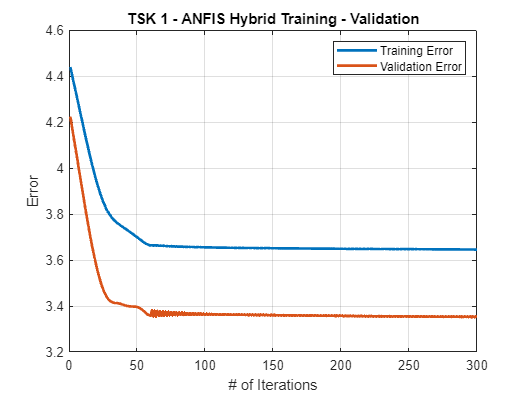

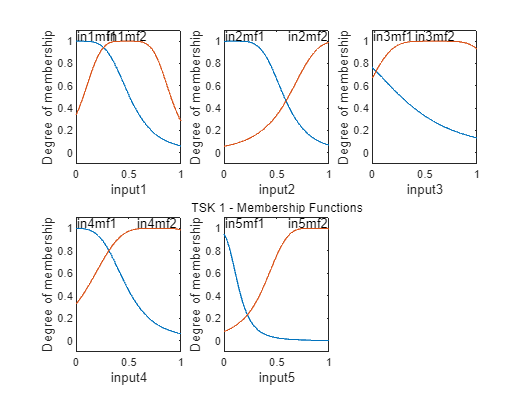

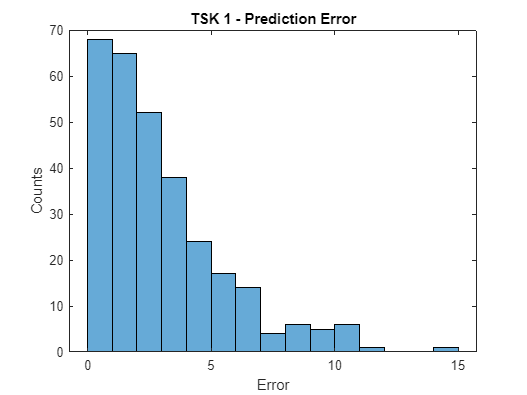

performanceStats = zeros(4,4);

%TSK-1
[RMSE, R2, NMSE, NDEI] = stats_graphs(1, tsk1_valFIS, chkData, tstData, tsk1_trnError, tsk1_valError, 1);

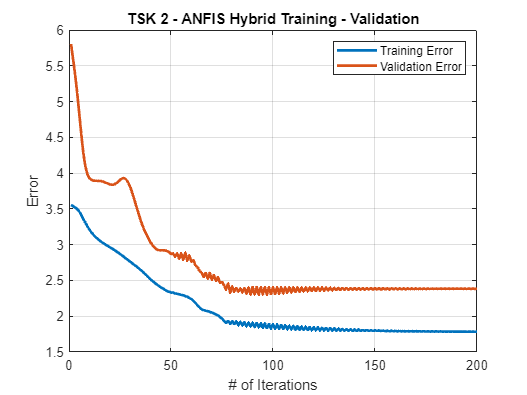

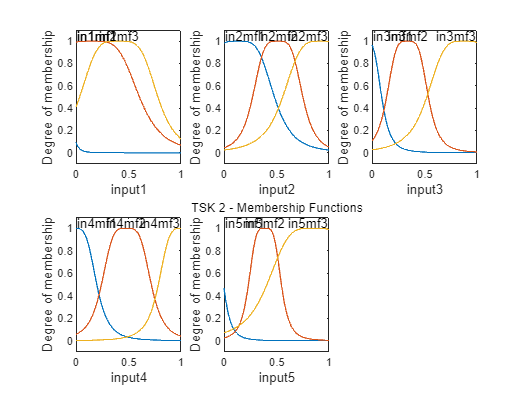

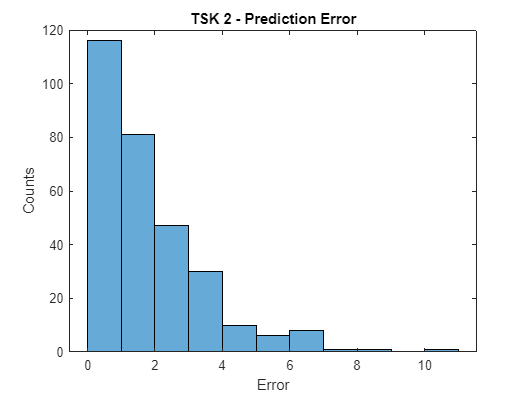

performanceStats(1,:) = [RMSE, R2, NMSE, NDEI];

%TSK-2
[RMSE, R2, NMSE, NDEI] = stats_graphs(2, tsk2_valFIS, chkData, tstData, tsk2_trnError, tsk2_valError, 1);

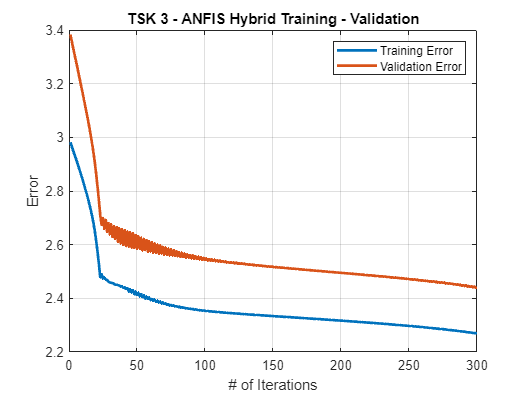

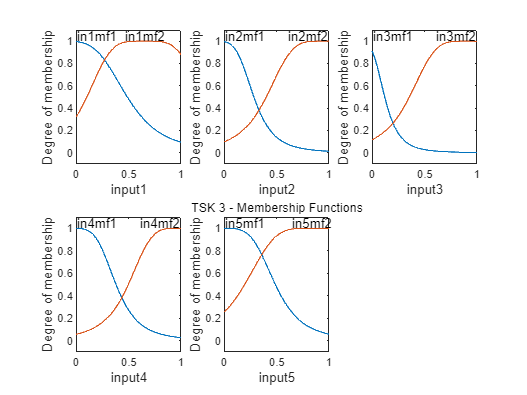

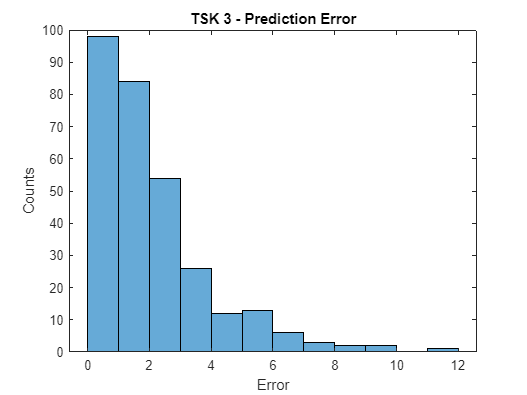

performanceStats(2,:) = [RMSE, R2, NMSE, NDEI];

%TSK-3
[RMSE, R2, NMSE, NDEI] = stats_graphs(3, tsk3_valFIS, chkData, tstData, tsk3_trnError, tsk3_valError, 1);

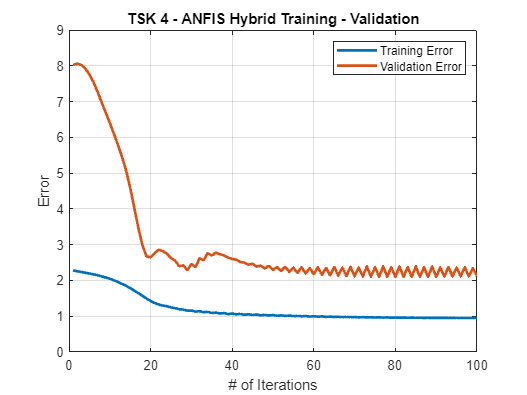

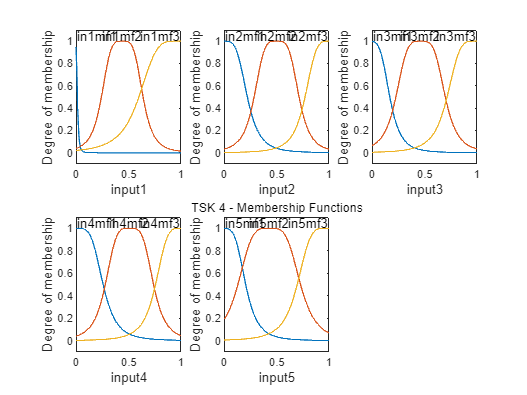

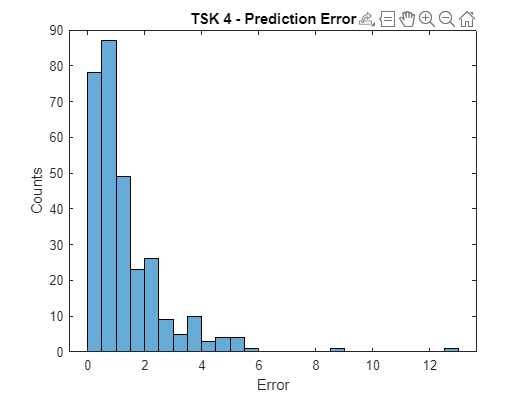

performanceStats(3,:) = [RMSE, R2, NMSE, NDEI];

%TSK-4
[RMSE, R2, NMSE, NDEI] = stats_graphs(4, tsk4_valFIS, chkData, tstData, tsk4_trnError, tsk4_valError, 1);

performanceStats(4,:) = [RMSE, R2, NMSE, NDEI];

%% Form Results Table
colNames = {'RMSE','R2','NMSE','NDEI'};
rowNames = {'TSK-1','TSK-2','TSK-3','TSK-4'};
performanceStats = array2table(performanceStats,'VariableNames',colNames,'RowNames',rowNames);